# 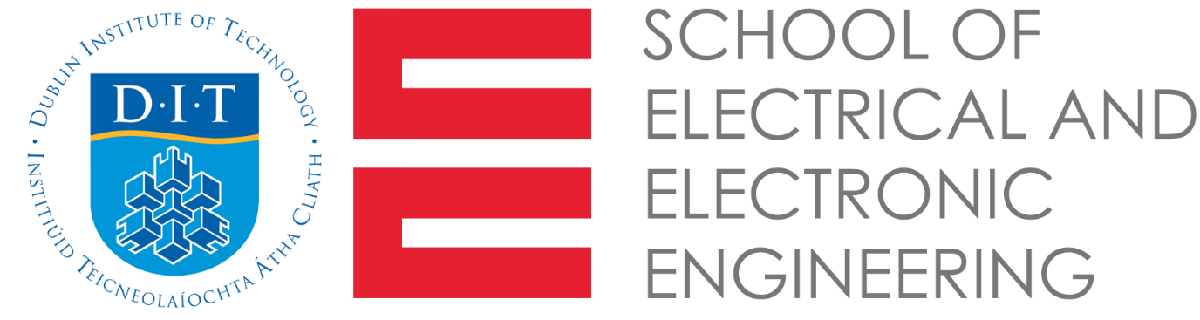

# Frequency response report

Stephen Sheridan C16746195

DIT021A/3

Lecturer Dr. Emma Robinson

## Instructions

Please ensure the workspace file Report1.mat is in the active directory then click 'Run' above. 

For the best viewing experience select the 'View results inline' option to the right.

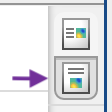

load Frequency1.mat;

## Introduction

The frequency response of a system is, simply put, the study of how a system responds to various input frequencies. This helps build a mathematical model of the system so predictions can be made about how it will behave, when it might become unstable etc. The resulting model can then be used to design a suitable controller for that system.

This report sets out to test these theories and to demonstrate the tools and techniques used to examine such a model and draw conclusions from the results.

The system used for this report was a CE110 Servo Trainer. Three sets of tests were previously performed to build a profile of the system and test the response of the unit. A speed test was performed where the input voltage was varied and the speed in rpm could be compared to the voltage output of the tachometer. There was also a position test where the position of the shaft was adjusted and compared to the voltage output of the position sensor. Finally a step test was performed to ascertain the open loop gain and time constant and thus the open loop transfer function. 

#### Fig.1 Servo Trainer [1]

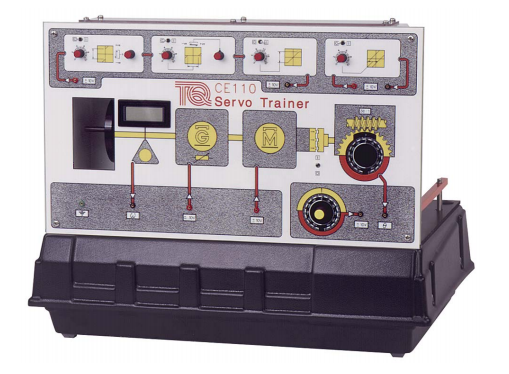

## Theory

The servo trainer as a system contains both electrical and mechanical elements. As the motor has copper coils meaning there is an inductive element and thus we can conclude that it is not a first order system. However as the reactive loss in the system is a lot smaller than the mechanical losses it was treated as such for all initial testing.

#### Fig.2 Block diagram of the servo trainer 

From the tests performed the time constant of the system was found to be $\tau$= 0.5028 

and the gain G(s) = 0.9592

Therefore the open loop transfer function = 

This transfer function will be used as a starting point to analyse the system. It will be shown how tools like the  bode plot may be used to analyse the behaviour of this system. All of this shall be compared with the actual system. 

#### Fig.3 Bode plot (theoretical)

*Please run the following section of code to produce a bode plot from the transfer function.*

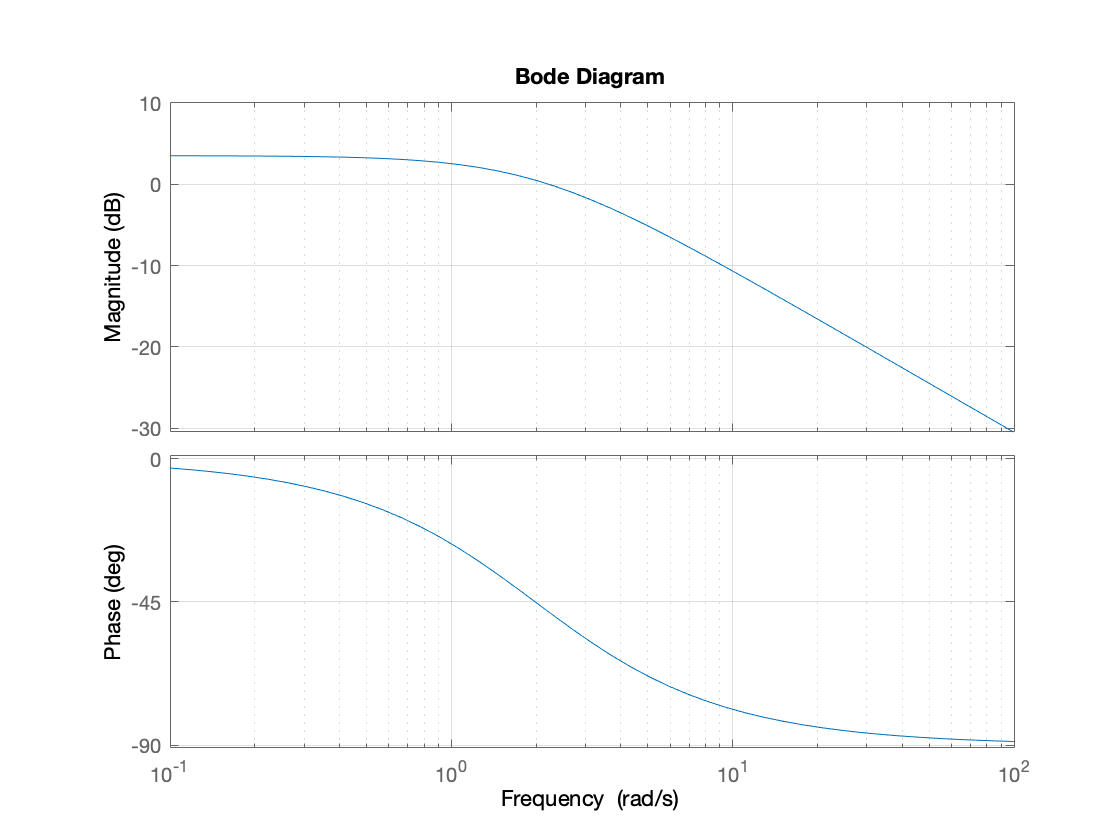

sys=tf(1.5,[0.5028 1]);
bode(sys)
grid on

The bode plot above is typical of a first order system. The dc gain is 0.9592 and the gain drops off at rate of 20dB / decade beyond the break frequency of around 2 rads/s (1.988 rads/s calculated from the transfer function). At this frequency the phase is shifted by -45˚ note also that the phase shift begins one decade earlier and finishes one decade later with a total phase shift of -90˚. It can already be stated that this is a stable system as the phase shift never reaches -180˚, both the phase margin and the gain margin are infinite.

The values above can be changed to view how they affect the response of the system. For example if the gain is changed this merely transposes the plot higher or lower, if the time constant is altered this moves the break frequency along the frequency axis.

## Method

To determine the frequency response of the actual system a sinusoidal signal was sent to the motor input. This had an amplitude of 2V and a dc offset of 5V to overcome the deadzone of the machine and to prevent the motor changing direction. The following frequencies (rads/s) were applied [0.20, 0.70,    1,	1.50,   2,	2.50,  3,	5,	10,	19,	20,	50]. These frequencies were chosen to build a bode plot so they are clustered around the break frequency (2 rads/s) and one decade either side. The resulting output was recorded from the tachometer. This was then analysed and the magnitude and phase shift were measured. 

Below is the Matlab code used to perform the test and to plot the results ready for analysis. [2]

## Results

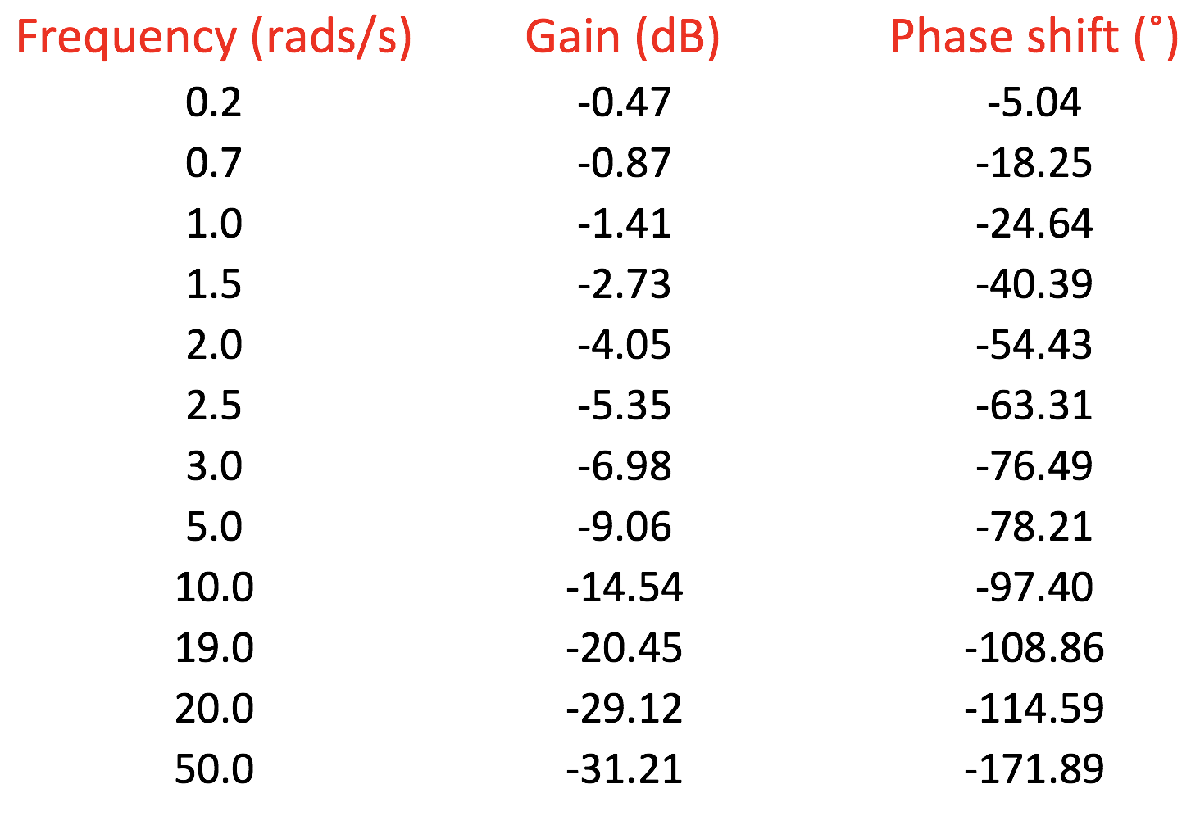

#### Plots.

The following is a selection of key plots from the frequency response test.

####  Fig.4 response at 0.2 rads/s

At 0.2 rads/s there is little attenuation and minimal phase shift much as expected. However the phase shift is not zero indicating there is an extra element in the system.

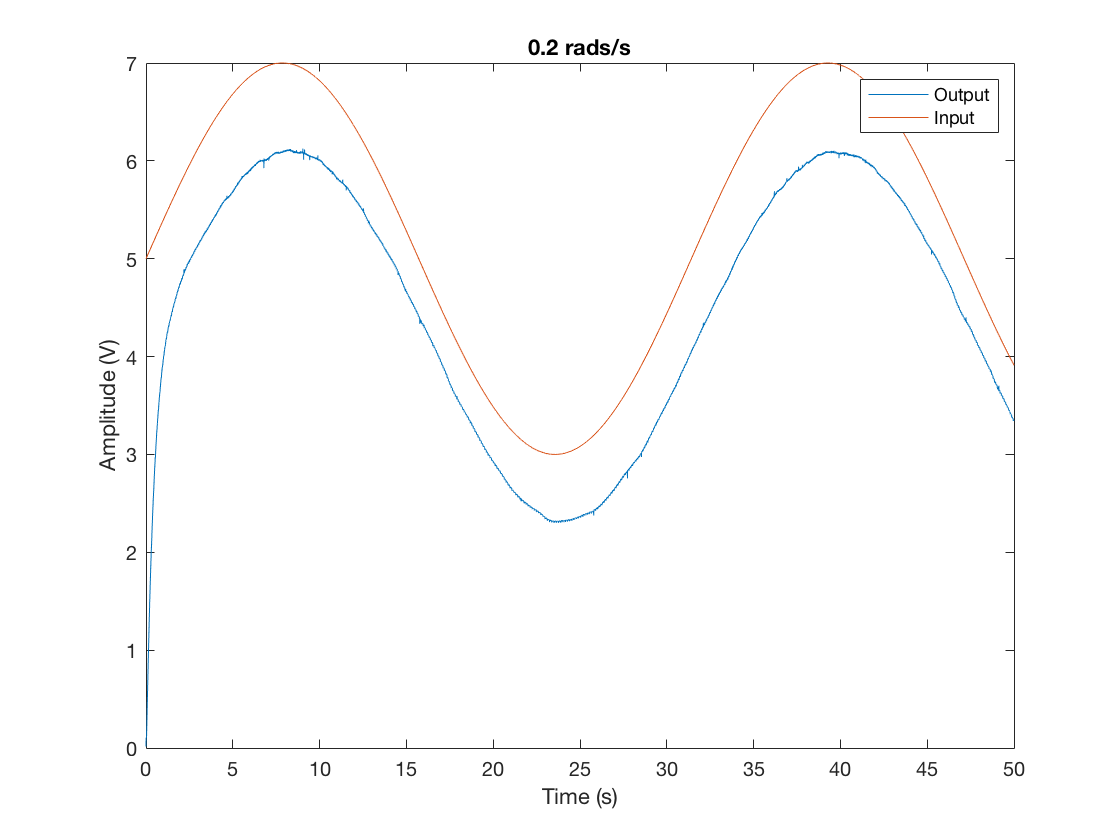

####  Fig.5 response at 2 rads/s

At 2 rads/s (the break frequency) the phase shift is -54.4˚, for a first order system would usually be -45˚.

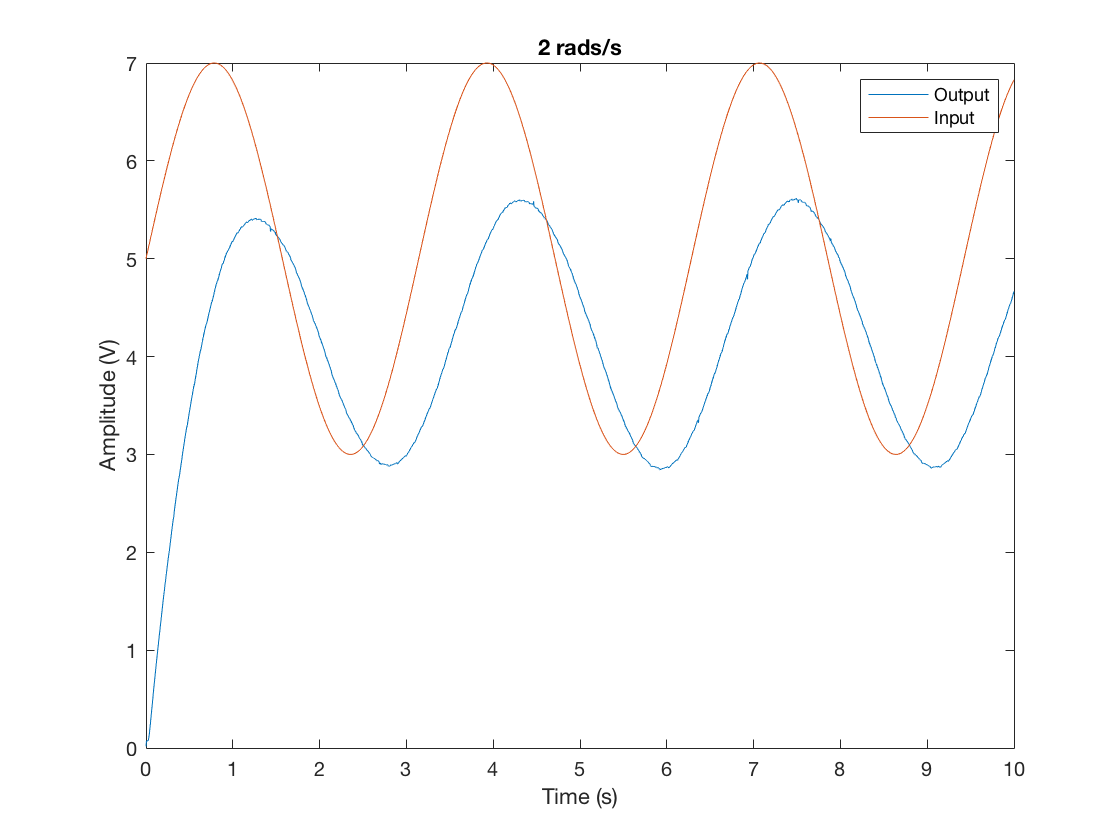

####  Fig.6 response at 3 rads/s

The next two plots at 3 rads/s and 5 rads/s show very little difference in phase shift. Measured the difference is just 1.72˚.

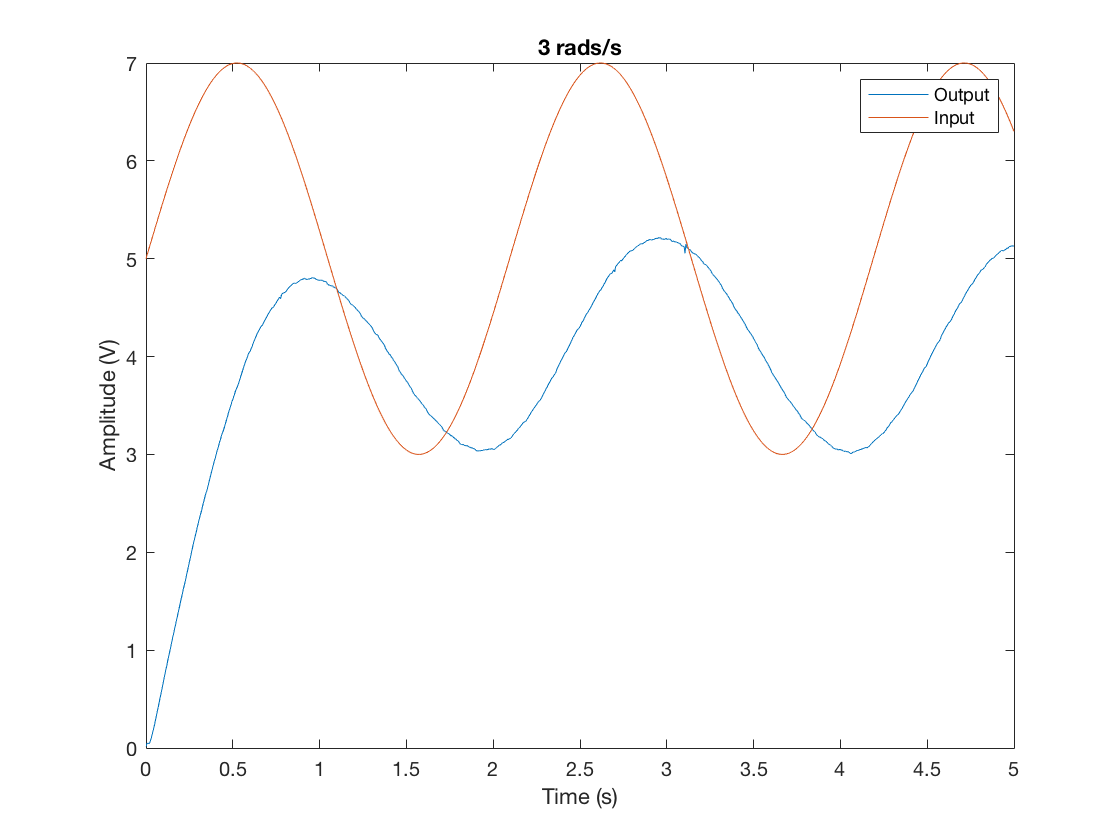

####  Fig.7 response at 5 rads/s

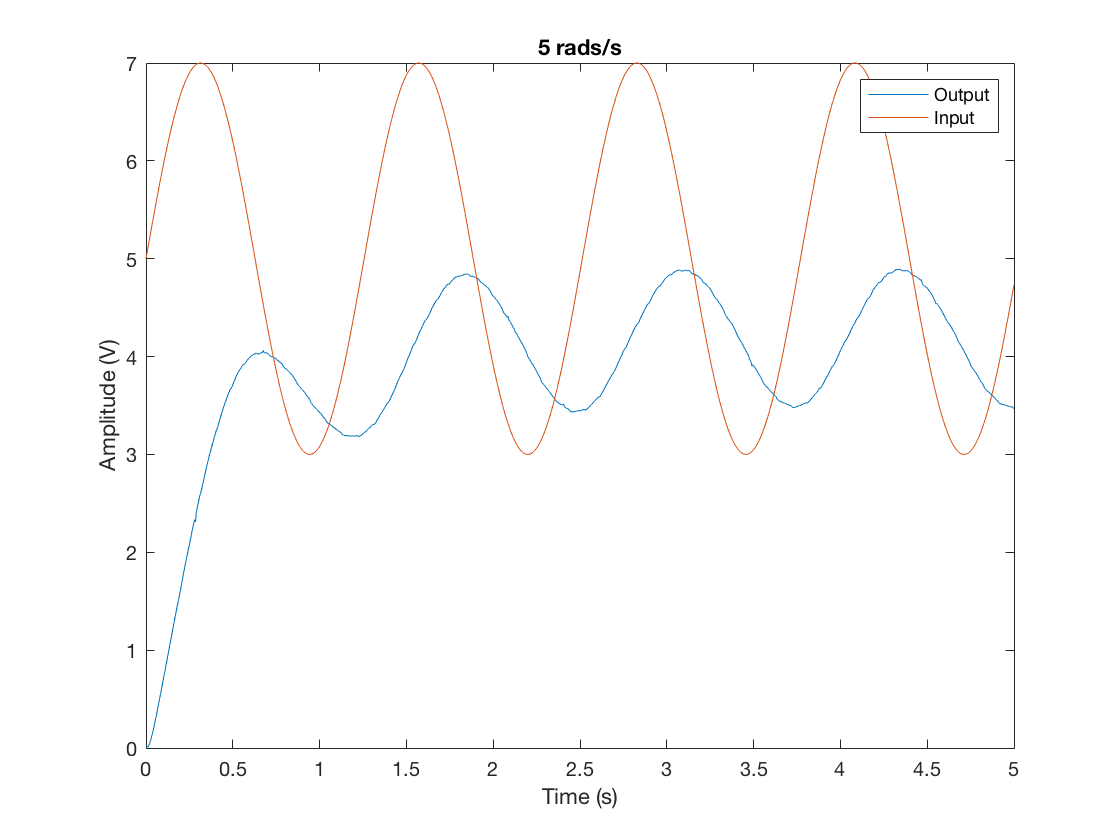

####  Fig.8 response at 50 rads/s

At 50 rads/s the output is attenuated to -31.2dB as opposed to -28dB expected. Beyond this frequency it becomes very difficult to measure the phase shift. 

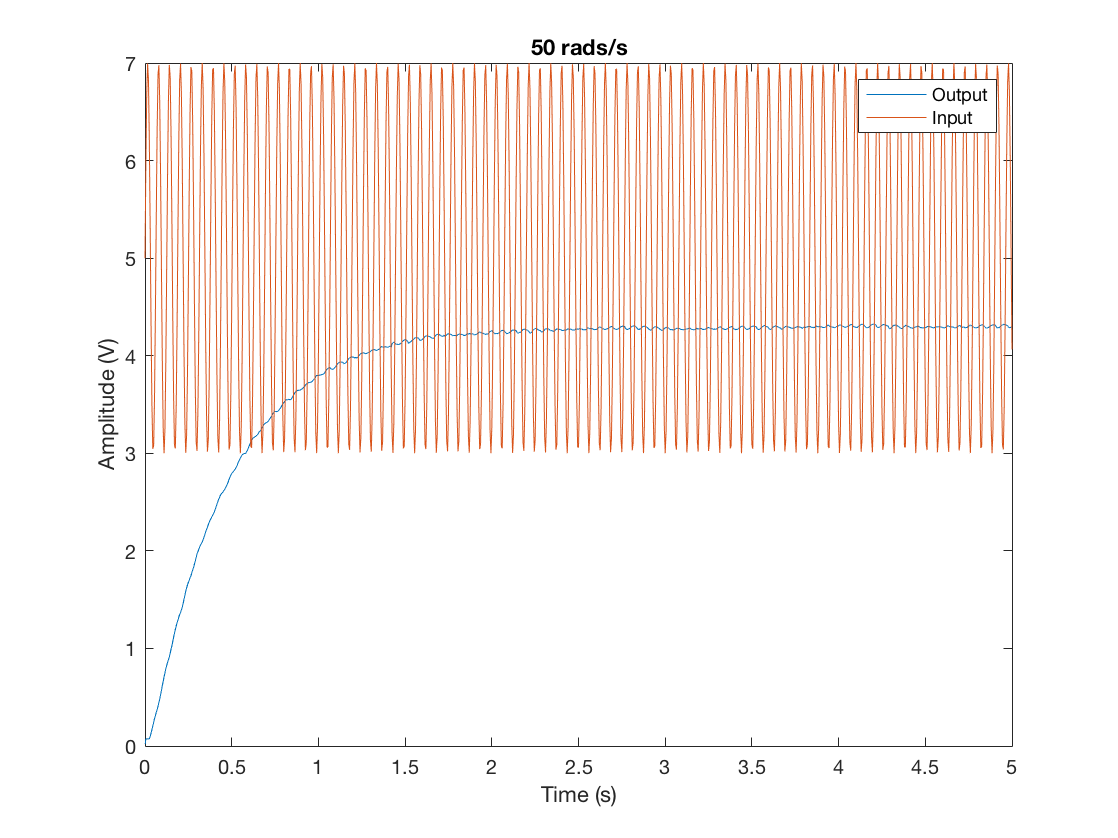

#### Fig.9 Bode plot  (actual)

*Please run the following section of code to display a bode plot from the recorded values*

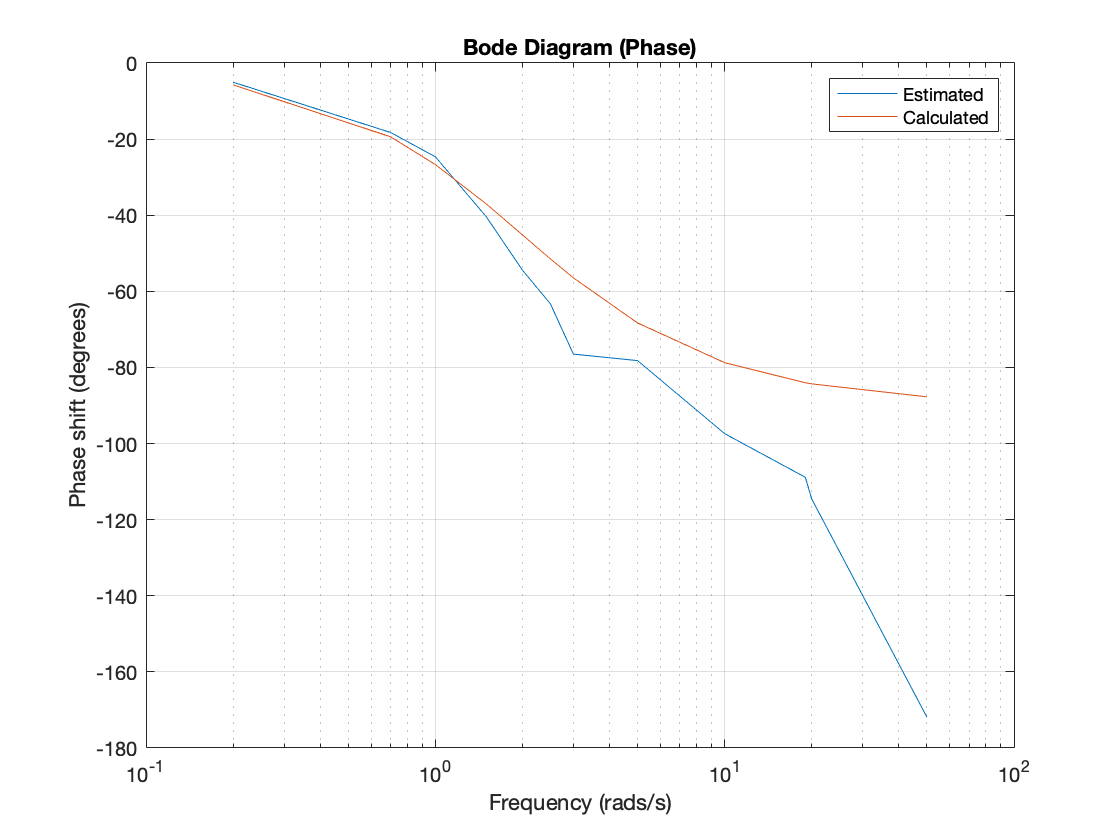

semilogx(Phaseshift(:,1), -Phaseshift(:,2))
hold on
semilogx(Phaseshift(:,1), Phaseshift(:,3))
xlabel('Frequency (rads/s)');
ylabel('Phase shift (degrees)');
legend('Estimated', 'Calculated');
title('Bode Diagram (Phase)')
hold off
grid on

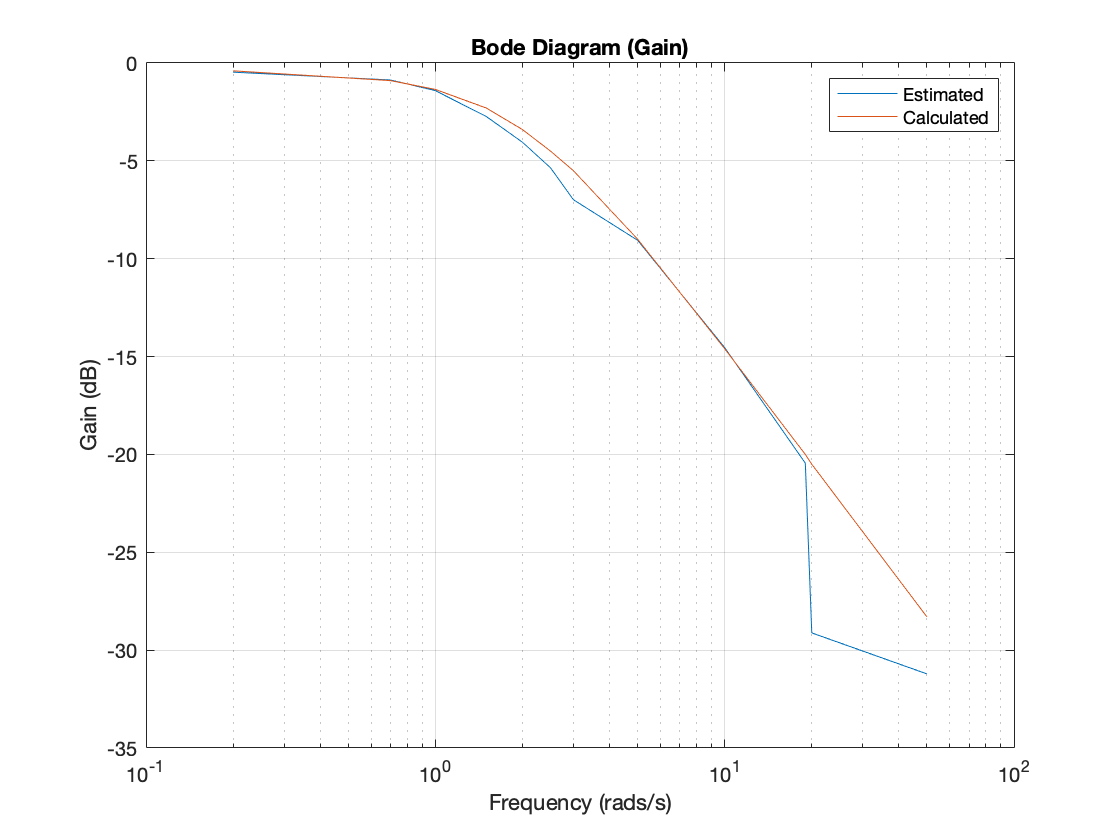

semilogx(Gain(:,1), Gain(:,3))
hold on
semilogx(Gain(:,1), gain_y)
hold off
xlabel('Frequency (rads/s)');
ylabel('Gain (dB)');
title('Bode Diagram (Gain)')
legend('Estimated', 'Calculated');
grid on

## Discussion

The bode plot above shows that the difference between the derived transfer function and the actual response of the system. It can clearly be seen that there is at least one more first order element in the system as there is a second shift in phase at around 3 rads/s. This would imply that this element has a break frequency of 0.3 rads/s (one decade before the shift occurs). Also note that the phase shift is moving towards -180 degrees, way beyond the expected -90 degrees that would occur if the system was first order.

As a second order system the gain margin is infinite and as the dc gain is less than zero the phase margin is also infinite highlighting again that this is a stable system.

#### Fig.10 Asymptotes

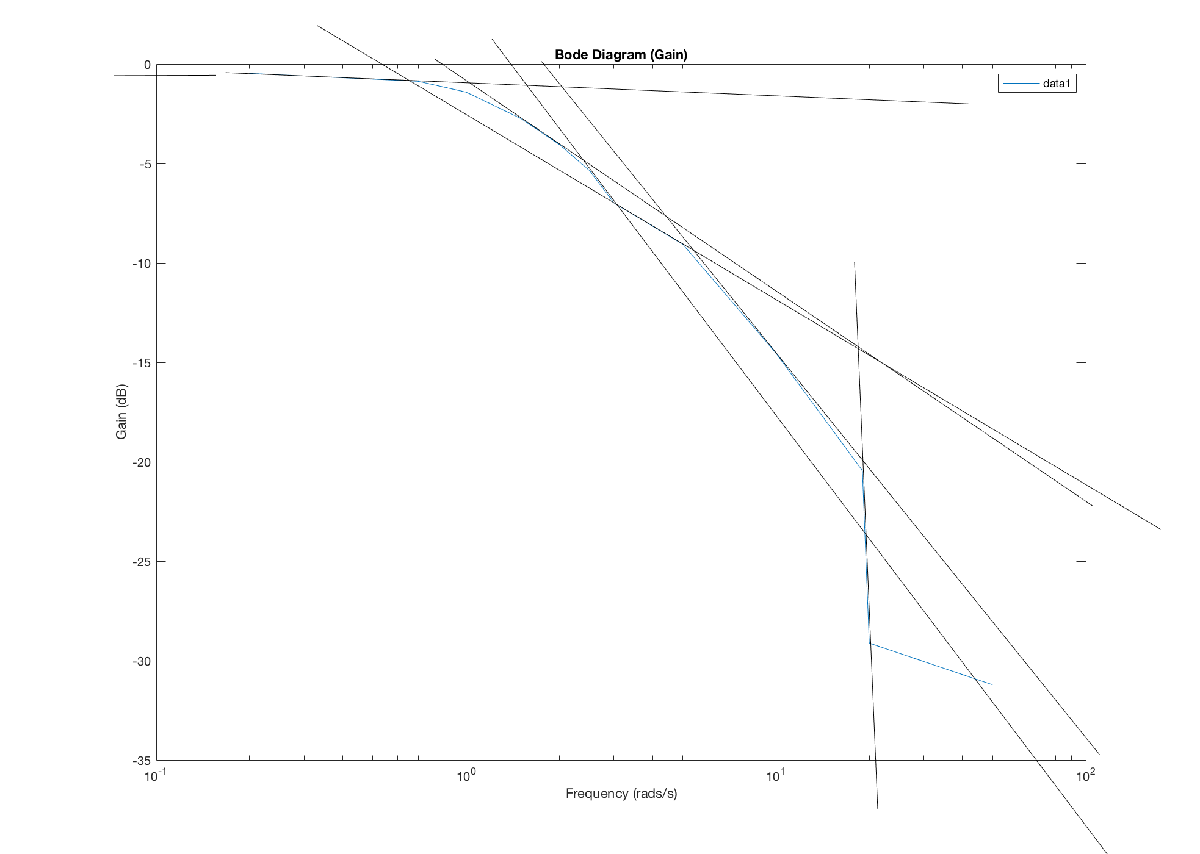

So why is all this important and how is a bode plot useful? This information can be used to build a more accurate model of a system and ultimately used to design a suitable controller depending on requirements. In Fig.10 lines have been drawn along the asymptotes and used to measure the falloff rates of the gain. The first four elements are as follows. At 1 rad/s the rate is -10dB/decade, at 2 rads/s it's -20dB/decade,  at 3 rads/s it returns to -10dB/decade and at at 5rads/s the rate is -20db/decade once more. A first order system would normally have a falloff rate of -20dB/decade beyond the break frequency and -40dB/decade for a second order system. It is obvious therefore that this is a much more complicated system than our transfer function describes. It is possible to use this technique to derive a fuller and more accurate transfer function of this system but it is beyond the scope of this report.

## Conclusions

The technique for performing obtaining a frequency response of a system has been outlined and the importance and usefulness of such tests have been discussed. This system was modelled as a first order system because the influence of the second element was expected to be marginal. This was found to be relatively true as the second element becomes evident at 3 rads/s at which point the output has been attenuated to -6dB or 8.9%. A quick look at the bode plot shows that there are more elements to this system as the rate of the phase shift and gain falloff change multiple times. It is however an inherently stable system.

#### References.

[1]  [CE110 Servo Trainer (manual) ] TecQuipment Ltd 2010

[1] Code adapted from  [DCServoTest.mlx  01/10/2018] Dr. Emma Robinson.